# Lab 3 IMU Stationary Data Analysis

clear
clc

statbag=rosbag('stationary.bag');


% getting time in seconds from bagfile

bSel = select(statbag, 'Topic', '/imu');
msgStructs = readMessages(bSel,"DataFormat","struct");
time_secs = double(cellfun(@(m) m.Header.Stamp.Sec,msgStructs));
time_nsecs = double(cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs));

time = time_secs + (time_nsecs * 10^-9);
time = time - time(1);


% Getting out the data

% Euler Angle Positions

% getting quaternion positions first (w,x,y,z)
quatpositions= zeros(length(time),4);

quatpositions(:,1) = double(cellfun(@(m) m.Imu.Orientation.W,msgStructs)); % w of quaternion
quatpositions(:,2) = double(cellfun(@(m) m.Imu.Orientation.X,msgStructs)); % x of quaternion
quatpositions(:,3) = double(cellfun(@(m) m.Imu.Orientation.Y,msgStructs)); % y of quaternion
quatpositions(:,4) = double(cellfun(@(m) m.Imu.Orientation.Z,msgStructs)); % z of quaternion

% getting euler angles from quaternion (again, format of quatpositions is
% W,X,Y,Z. Format of eulerpositions after quat2eul is z,y,x but I'm going
% to switch the columns so the eulerpositions format is *Actually* X,Y,Z
% UNIT OF euler angles is radians

eulerpositions = quat2eul(quatpositions);
% switching the columns
dummyColumn = eulerpositions(:,1);
eulerpositions(:,1) = eulerpositions(:,3);
eulerpositions(:,3) = dummyColumn;


% Angular Velocity (format of columns is in X,Y,Z), UNITS are in rad/s
angvels = zeros(length(time),3);
angvels(:,1) = double(cellfun(@(m) m.Imu.AngularVelocity.X,msgStructs));
angvels(:,2) = double(cellfun(@(m) m.Imu.AngularVelocity.Y,msgStructs));
angvels(:,3) = double(cellfun(@(m) m.Imu.AngularVelocity.Z,msgStructs));


% Linear Acceleration

% linaccel is an array containing linear acceleration data. UNITS are in
% m/s^2, the columns 1,2, and 3 are X,Y,Z respectively
linaccel = zeros(length(time),3);
linaccel(:,1) = double(cellfun(@(m) m.Imu.LinearAcceleration.X,msgStructs));
linaccel(:,2) = double(cellfun(@(m) m.Imu.LinearAcceleration.Y,msgStructs));
linaccel(:,3) = double(cellfun(@(m) m.Imu.LinearAcceleration.Z,msgStructs));

% Magnetic Field

% magfield is an array containing the magnetometer data (which measures
% strength and direction of a magnetic field). UNITS are in Teslas
% (converted from Gauss in python driver) and columns 1,2,3 are X,Y,Z
% respectively

magfield = zeros(length(time),3);
magfield(:,1) = double(cellfun(@(m) m.MagField.MagneticField_.X,msgStructs));
magfield(:,2) = double(cellfun(@(m) m.MagField.MagneticField_.Y,msgStructs));
magfield(:,3) = double(cellfun(@(m) m.MagField.MagneticField_.Z,msgStructs));



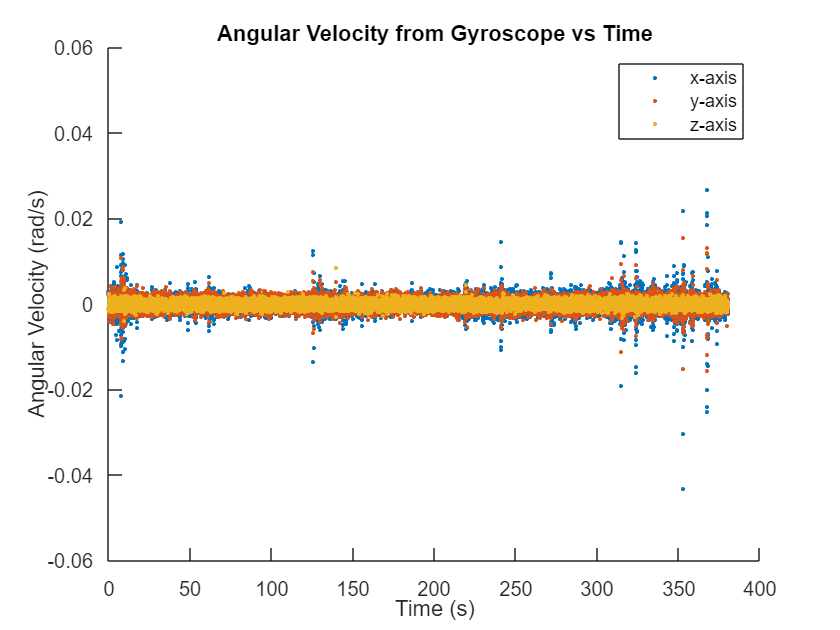

% Gyro Angular Velocity vs Time plot (Fig 0)

scatter(time,angvels(:,1),'.'); % x angular velocity vs time
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocity from Gyroscope vs Time')
hold on
scatter(time,angvels(:,2),'.'); % y angular velocity vs time
scatter(time,angvels(:,3),'.'); % z angular velocity vs time
hold off
legend('x-axis','y-axis','z-axis');

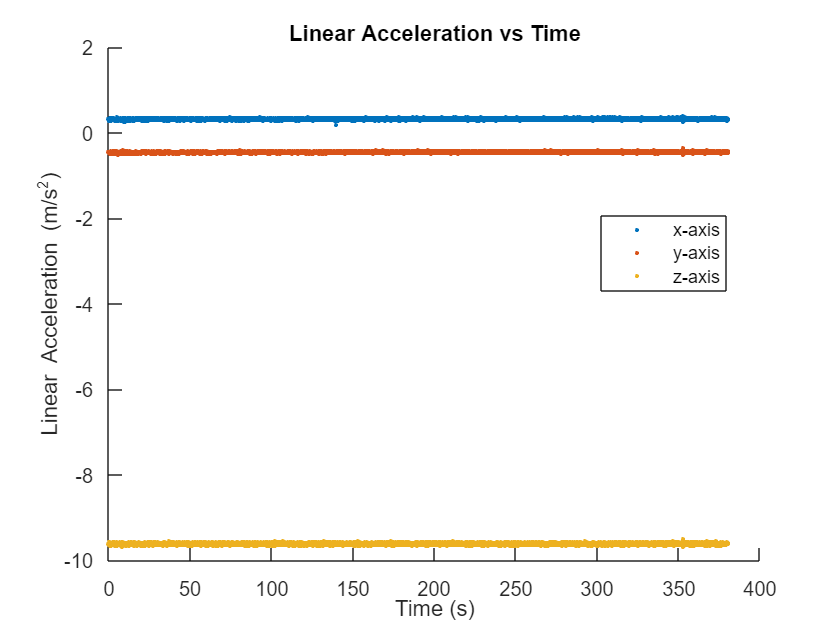

% Linear Acceleration vs Time plot (Fig 1)

scatter(time,linaccel(:,1),'.'); % x linear acceleration vs time
xlabel('Time (s)');
ylabel('Linear Acceleration (m/s^2)');
title('Linear Acceleration vs Time');
hold on
scatter(time,linaccel(:,2),'.'); % y linear acceleration vs time
scatter(time,linaccel(:,3),'.'); % z linear acceleration vs time
hold off
legend('x-axis','y-axis','z-axis');
legend("Position", [0.71687,0.53968,0.14821,0.11905])

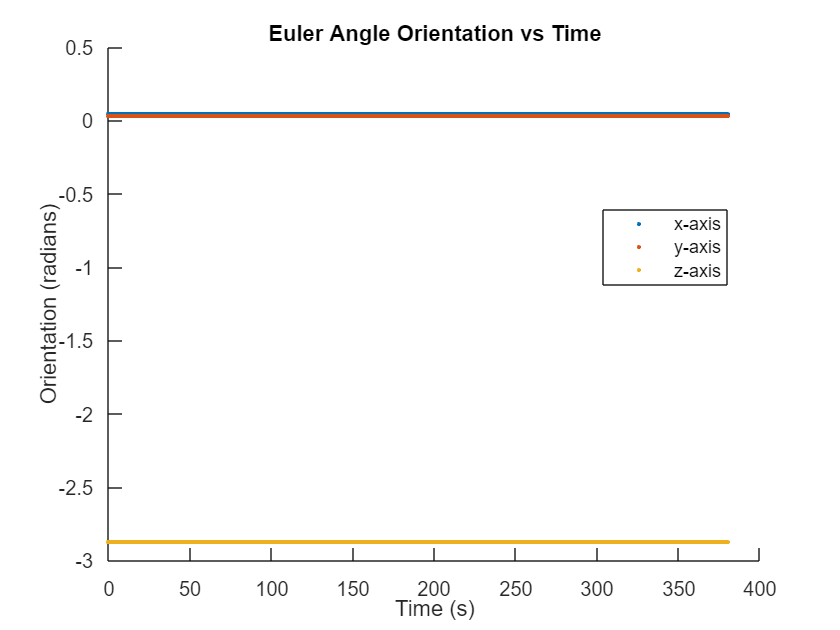

% Euler Angle/Orientation vs Time (Fig 2)

scatter(time,eulerpositions(:,1),'.'); % x euler angle vs time
xlabel('Time (s)');
ylabel('Orientation (radians)');
title('Euler Angle Orientation vs Time');
hold on
scatter(time,eulerpositions(:,2),'.'); % y euler angle vs time
scatter(time,eulerpositions(:,3),'.'); % z euler angle vs time
hold off
legend('x-axis','y-axis','z-axis');

legend("Position", [0.71845,0.54921,0.14821,0.11905])

% calculating mean and median for each orientation, linear acceleration,
% and angular velocity

% the following are arrays/'horizontal' lists, where each contains either
% the means or medians of some aspect of the imu's data that was plotted
% against time. The mean and median functions work by taking the average of
% the data values in the COLUMNS of the array, which works well for how
% I've set up my arrays. Great!

eulerposition_means = mean(eulerpositions);
eulerposition_medians = median(eulerpositions);


linaccel_means = mean(linaccel);
linaccel_medians = median(linaccel);


angvels_means = mean(angvels);
angvels_medians = median(angvels);


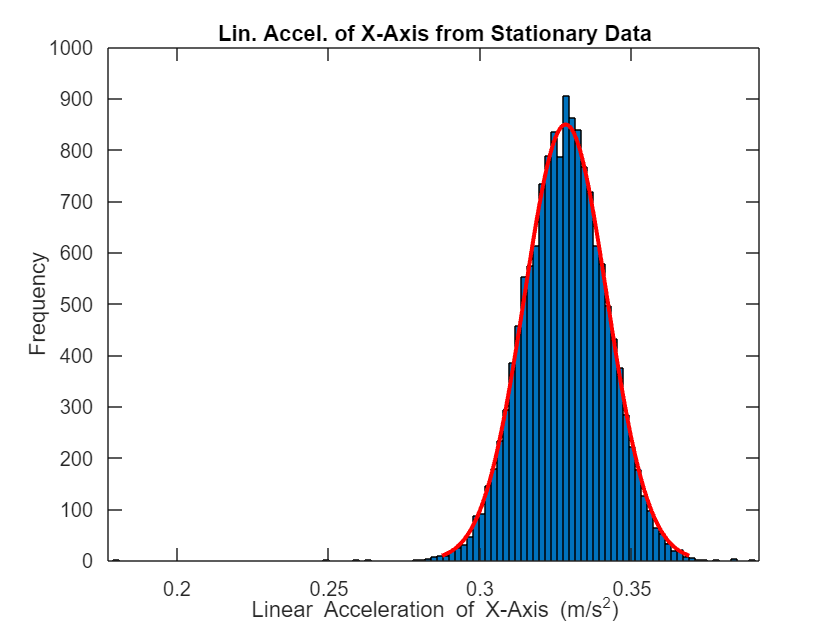

numberObins_accX = length(histcounts(linaccel(:,1)));
histfit(linaccel(:,1), numberObins_accX);
xlabel('Linear Acceleration of X-Axis (m/s^2)');
ylabel('Frequency');
title('Lin. Accel. of X-Axis from Stationary Data');




subplot(2,3,1)
% Histogram of x-axis linear acceleration (Fig 3)
numberObins_accX = length(histcounts(linaccel(:,1)));
histfit(linaccel(:,1), numberObins_accX);
xlabel('Linear Acceleration of X-Axis (m/s^2)');
ylabel('Frequency');
title('Lin. Accel. of X-Axis from Stationary Data');

hold on
xline(linaccel_means(1,1), 'Color', 'r', 'LineWidth', .5,'Label','Mean=0.3282','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(linaccel_medians(1,1), 'Color', 'k', 'LineWidth', .5,'Label','Median=0.3280','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off

datastddev_accX = std(linaccel(:,1)) % standard deviation of x-axis linear acceleration

datastddev_accX = 0.0136

% first dev out
onestdleft_accX = linaccel_means(1,1) - datastddev_accX;
onestdright_accX = linaccel_means(1,1) + datastddev_accX;
percentIn1stDevs_accX = sum((onestdleft_accX<linaccel(:,1)) & (linaccel(:,1)<onestdright_accX))/numel(linaccel(:,1))

percentIn1stDevs_accX = 0.6766


% second dev out
twostdleft_accX = linaccel_means(1,1) - (2*datastddev_accX);
twostdright_accX = linaccel_means(1,1) + (2*datastddev_accX);
percentIn2ndDevs_accX = sum((twostdleft_accX<linaccel(:,1)) & (linaccel(:,1)<twostdright_accX))/numel(linaccel(:,1))

percentIn2ndDevs_accX = 0.9554




subplot(2,3,2)
% Histogram of y-axis linear acceleration
numberObins_accY = length(histcounts(linaccel(:,2)))-1;
histfit(linaccel(:,2), numberObins_accY);
xlabel('Linear Acceleration of Y-Axis (m/s^2)');
ylabel('Frequency');
title('Lin. Accel. of Y-Axis from Stationary Data');

hold on
xline(linaccel_means(1,2), 'Color', 'r', 'LineWidth', .5,'Label','Mean=-0.4471','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(linaccel_medians(1,2), 'Color', 'k', 'LineWidth', .5,'Label','Median=-0.4470','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off

datastddev_accY = std(linaccel(:,2)) % standard deviation of x-axis linear acceleration

datastddev_accY = 0.0126

% first dev out
onestdleft_accY = linaccel_means(1,2) - datastddev_accY;
onestdright_accY = linaccel_means(1,2) + datastddev_accY;
percentIn1stDevs_accY = sum((onestdleft_accY<linaccel(:,2)) & (linaccel(:,2)<onestdright_accY))/numel(linaccel(:,2))

percentIn1stDevs_accY = 0.6817


% second dev out
twostdleft_accY = linaccel_means(1,2) - (2*datastddev_accY);
twostdright_accY = linaccel_means(1,2) + (2*datastddev_accY);
percentIn2ndDevs_accY = sum((twostdleft_accY<linaccel(:,2)) & (linaccel(:,2)<twostdright_accY))/numel(linaccel(:,2))

percentIn2ndDevs_accY = 0.9544



subplot(2,3,3)
% Histogram of z-axis linear acceleration
numberObins_accZ = length(histcounts(linaccel(:,3)));
histfit(linaccel(:,3), numberObins_accZ);
xlabel('Linear Acceleration of Z-Axis (m/s^2)');
ylabel('Frequency');
title('Lin. Accel. of Z-Axis from Stationary Data');

hold on
xline(linaccel_means(1,3), 'Color', 'r', 'LineWidth', .5,'Label','Mean=-9.598','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(linaccel_medians(1,3), 'Color', 'k', 'LineWidth', .5,'Label','Median=-9.598','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off

datastddev_accZ = std(linaccel(:,3)) % standard deviation of x-axis linear acceleration

datastddev_accZ = 0.0171

% first dev out
onestdleft_accZ = linaccel_means(1,3) - datastddev_accZ;
onestdright_accZ = linaccel_means(1,3) + datastddev_accZ;
percentIn1stDevs_accZ = sum((onestdleft_accZ<linaccel(:,3)) & (linaccel(:,3)<onestdright_accZ))/numel(linaccel(:,3))

percentIn1stDevs_accZ = 0.6950


% second dev out
twostdleft_accZ = linaccel_means(1,3) - (2*datastddev_accZ);
twostdright_accZ = linaccel_means(1,3) + (2*datastddev_accZ);
percentIn2ndDevs_accZ = sum((twostdleft_accZ<linaccel(:,3)) & (linaccel(:,3)<twostdright_accZ))/numel(linaccel(:,3))

percentIn2ndDevs_accZ = 0.9562


subplot(2,3,4)
% Histogram of x-axis angular velocity (gyroscope
numberObins_velX = length(histcounts(angvels(:,1)));
histfit(angvels(:,1), numberObins_velX);
xlabel('Angular Velocity of X-Axis (rad/s)');
ylabel('Frequency');
title('Ang. Velocities of X-Axis from Stationary Data');

hold on
xline(angvels_means(1,1), 'Color', 'r', 'LineWidth', .5,'Label','Mean=-1.6688e-7','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(angvels_medians(1,1), 'Color', 'k', 'LineWidth', .5,'Label','Median=-1.6000e-7','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off

datastddev_velX = std(angvels(:,1)) % standard deviation of x-axis angular velocity

datastddev_velX = 0.0019

% first dev out
onestdleft_velX = angvels_means(1,1) - datastddev_velX;
onestdright_velX = angvels_means(1,1) + datastddev_velX;
percentIn1stDevs_velX = sum((onestdleft_velX<angvels(:,1)) & (angvels(:,1)<onestdright_velX))/numel(angvels(:,1))

percentIn1stDevs_velX = 0.8097


% second dev out
twostdleft_velX = angvels_means(1,1) - (2*datastddev_velX);
twostdright_velX = angvels_means(1,1) + (2*datastddev_velX);
percentIn2ndDevs_velX = sum((twostdleft_velX<angvels(:,1)) & (angvels(:,1)<twostdright_velX))/numel(angvels(:,1))

percentIn2ndDevs_velX = 0.9703



subplot(2,3,5)
% Histogram of y-axis angular velocity (gyroscope)
numberObins_velY = length(histcounts(angvels(:,2)));
histfit(angvels(:,2), numberObins_velY);
xlabel('Angular Velocity of Y-Axis (rad/s)');
ylabel('Frequency');
title('Ang. Velocities of Y-Axis from Stationary Data');

hold on
xline(angvels_means(1,2), 'Color', 'r', 'LineWidth', .5,'Label','Mean=1.9567e-5','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(angvels_medians(1,2), 'Color', 'k', 'LineWidth', .5,'Label','Median=1.7000e-5','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off

datastddev_velY = std(angvels(:,2)) % standard deviation of Y-axis angular velocity

datastddev_velY = 0.0013

% first dev out
onestdleft_velY = angvels_means(1,2) - datastddev_velY;
onestdright_velY = angvels_means(1,2) + datastddev_velY;
percentIn1stDevs_velY = sum((onestdleft_velY<angvels(:,2)) & (angvels(:,2)<onestdright_velY))/numel(angvels(:,2))

percentIn1stDevs_velY = 0.7323


% second dev out
twostdleft_velY = angvels_means(1,2) - (2*datastddev_velY);
twostdright_velY = angvels_means(1,2) + (2*datastddev_velY);
percentIn2ndDevs_velY = sum((twostdleft_velY<angvels(:,2)) & (angvels(:,2)<twostdright_velY))/numel(angvels(:,2))

percentIn2ndDevs_velY = 0.9617

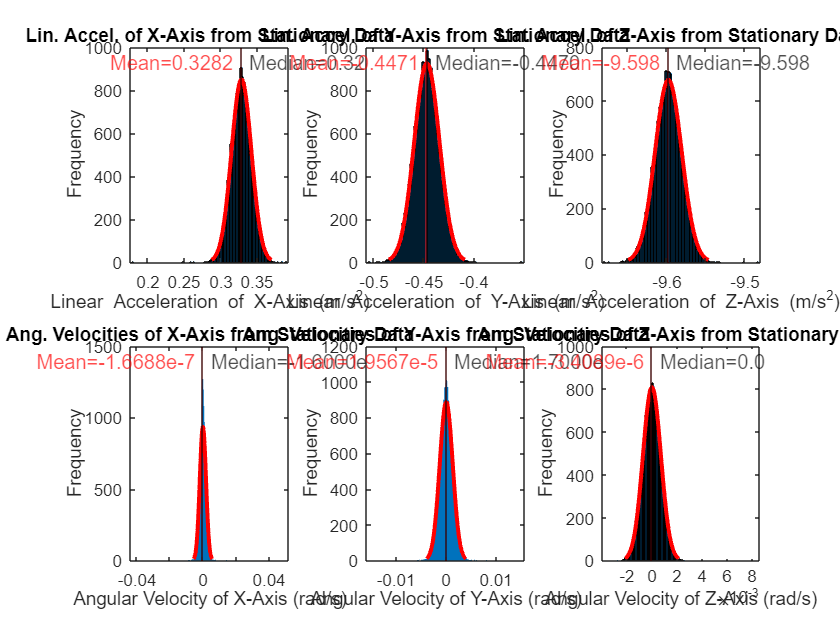




subplot(2,3,6)
% Histogram of z-axis angular velocity (gyroscope)
numberObins_velZ = length(histcounts(angvels(:,3)));
histfit(angvels(:,3), numberObins_velZ);
xlabel('Angular Velocity of Z-Axis (rad/s)');
ylabel('Frequency');
title('Ang. Velocities of Z-Axis from Stationary Data');

hold on
xline(angvels_means(1,3), 'Color', 'r', 'LineWidth', .5,'Label','Mean=-3.4089e-6','LabelHorizontalAlignment','left','LabelOrientation','horizontal');
xline(angvels_medians(1,3), 'Color', 'k', 'LineWidth', .5,'Label','Median=0.0','LabelHorizontalAlignment','right','LabelOrientation','horizontal');
hold off


datastddev_velZ = std(angvels(:,3)) % standard deviation of z-axis angular velocity

datastddev_velZ = 7.1716e-04

% first dev out
onestdleft_velZ = angvels_means(1,3) - datastddev_velZ;
onestdright_velZ = angvels_means(1,3) + datastddev_velZ;
percentIn1stDevs_velZ = sum((onestdleft_velZ<angvels(:,3)) & (angvels(:,3)<onestdright_velZ))/numel(angvels(:,3))

percentIn1stDevs_velZ = 0.6857


% second dev out
twostdleft_velZ = angvels_means(1,3) - (2*datastddev_velZ);
twostdright_velZ = angvels_means(1,3) + (2*datastddev_velZ);
percentIn2ndDevs_velZ = sum((twostdleft_velZ<angvels(:,3)) & (angvels(:,3)<twostdright_velZ))/numel(angvels(:,3))

percentIn2ndDevs_velZ = 0.9558